T=0.1;% constata de timp a sistemului
n=10;t=0:T/100:n*T;% timpul de simulare
u=(t<=T)/T;% semnal impuls unitate
subplot(121); % 2 subgrafice pe linie
plot(t,u,'LineWidth',2);% reprezentare grafica a semnalului u
axis([-0.1 n*T -1 13]); % setare suprafata de reprezentare
hold; % retine reprezentarea grafica din fereastra activa

Current plot held


plot([0 0],[-1 13],'--k',[-0.1 n*T],[0 0],'--k');
hold; % se renunta la mentinerea reperezentarilor curente

Current plot released


xlabel('Timp (sec)','FontSize',12); % comentariu pe abscisa
% comentariu ordonata
ylabel('$\delta(t)$','Fontsize',14,'interpreter', 'Latex');

subplot(122); % a doua subfereastra activa
% haşurare suprafaţă
area([0 0.1],[10 10],'FaceColor',[.5 .5 0.5]);
plot(t,u,'LineWidth',2);
axis([-0.1 4*T -1 13])
hold;plot([0 0],[-1 13],'--k',[-0.1 n*T],[0 0],'--k');

Current plot held


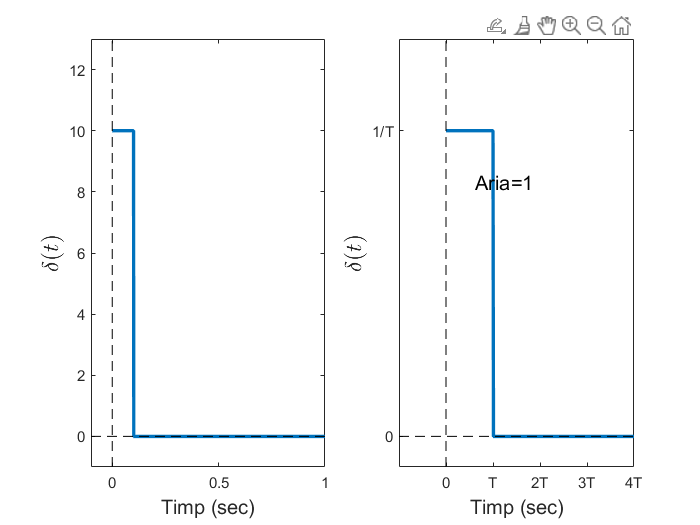

% precizarea punctelor active de pe abscisa
set(gca,'XTick',[0:T:4*T,9*T]);
% textul punctelor de pe abscisa
set(gca,'XTickLabel',{'0','T','2T','3T','4T','9T'})
% precizarea punctelor active de pe ordonata
set(gca,'YTick',[0 1/T]);
% denumirea punctelor considerate pe ordonata
set(gca,'YTickLabel',{'0','1/T'});
% plasare cu mouse-ul de text pe reprezentarea grafica
gtext('Aria=1','FontSize',12);
xlabel('Timp (sec)','FontSize',12);
ylabel('$\delta(t)$','Fontsize',14,'interpreter', 'Latex')